function[P_rect,P_1DInstant,P_1DrectG1,P1DrectG2, P_rect_nonGamma, P_rectMCAD1D, P_2D] = devcalcHybridACLossWave(conductorType, dimensions, freqE, BField)
 %% From [Taha2020] & [taha2024Access] 섞임

## 1. Skin Effect Mode

### Skin depth for frequency -> calcSkinDepth.m

$$\delta=1 / \sqrt{\pi \mu_c \sigma f}$$, $$$
\delta=\sqrt{\frac{2 \rho}{\omega \mu_0}}
$$$

where $\rho$ is the conductor resistivity, $\omega$ the angular frequency and $\mu_0$the permeability of free space.

$\sigma$ : Conductivity(sigma)

elec.T0.resistivity = 1.724E-8;  % 주어진 저항값 (옴·미터)
elec.T0.Conductivity = 1 / elec.T0.resistivity;  % 전기전도도 (S/m)
sigma=elec.T0.Conductivity;                      % [S/m]
rho  = 1/sigma    ;  % resistivity (옴·미터)
mu0  = 4*pi*10^-7 ;      % [H/m] 
mu_c=mu0          ; %도체와 공기중 투자율이 같은것으로 가정
omegaE=freq2omega(freqE);
% freqE=mech2elec(freqE,4)
% SkinDepth_delta=sqrt((2*rho)./(omegaE.*mu0))  ;     % [m]
% SkinDepth_delta_inmm=m2mm(SkinDepth_delta)  ;       %[mm]
% 주어진 매개변수로부터 스킨 깊이 계산
    % delta=SkinDepth_delta_inmm;   % in [mm]
    % delta = 1 ./ sqrt(pi * mu_c * sigma .* double(freqE)); %[m]
    % calcSkinDepth.m
    lactive=mm2m(dimensions(3));  %[m]


## 도체의 형태에 따라 다른 계산 수행

switch conductorType
    case 'rectangular'
        w = dimensions(1);   %[mm]
        w =mm2m(w);
        h = dimensions(2);   %[mm]
        h =mm2m(h);

#### *사각형 도체에 대한 수정된 스킨 깊이*


$$$\delta_w^{\prime}=\delta \cdot \sqrt{\frac{(w+h)} {(2 h)},} \quad \delta_h^{\prime}=\delta \cdot \sqrt{\frac{(w+h)} {(2 w)}$$$


% 사각형 도체에 대한 수정된 스킨 깊이
    delta         =mm2m(calcSkinDepth(freqE));
    delta_w_prime = delta.* sqrt((w + h) / (2 * h));
    delta_h_prime = delta.* sqrt((w + h) / (2 * w));

#### 무차원 형상파라미터


$$$\gamma, \gamma_w, \gamma_h, \gamma_w^{\prime}, \gamma_h^{\prime}$ Dimensionless parameters:
$$
\gamma=\frac{d}{\delta \cdot \sqrt{2}} \quad \gamma_w=\frac{w}{\delta} \quad \gamma_h=\frac{h}{\delta} \quad \gamma_w^{\prime}=\frac{w}{\delta_w^{\prime}} \quad \gamma_h^{\prime}=\frac{w}{\delta_h^{\prime}}
$$$$
       

            % 사각형 도체에 대한 무차원 매개변수
            gamma_w = w ./ delta;
            gamma_h = h ./ delta;   
            gamma_w_prime = w ./ delta_w_prime;
            gamma_h_prime = h ./ delta_h_prime;
            % gamma_h_prime_w = w ./ delta_h_prime;

### gamma의 활용 주목 (kelvin function)


$$$$
\frac{R_{\text {skin }}}{R_{D C}}=\frac{\gamma}{2} \cdot \frac{{ber}(\gamma) bei^{\prime}(\gamma)-b e i(\gamma) ber^{\prime}(\gamma)}{ber^{\prime 2}(\gamma)+bei^{\prime 2}(\gamma)}
$$$$
 

$ber_n, bei_n$ : kelvin function of order n

#### kelvin function


$$
{ber}_n(x)=\left(\frac{x}{2}\right)^n \sum_{k \geq 0} \frac{\cos \left[\left(\frac{3 n}{4}+\frac{k}{2}\right) \pi\right]}{k!\Gamma(n+k+1)}\left(\frac{x^2}{4}\right)^k
$$


$ber'_n, bei'_n$ : Derivative of kelvin function of order n

[19]  S. Ramo, J. R. Whinnery and V. Twersky, Fields and Waves in Modern Radio, vol. 7, AIP Publishing, 1954.

[한계]정현파 전류에 대해서만 적용됨 

[20]에서 각 고조파로 인한 손실을 합산할것을 제안 

[1984 P. S. Venkatraman], "Winding eddy current losses in switch mode power transformers due to rectangular wave currents," in Proc. 

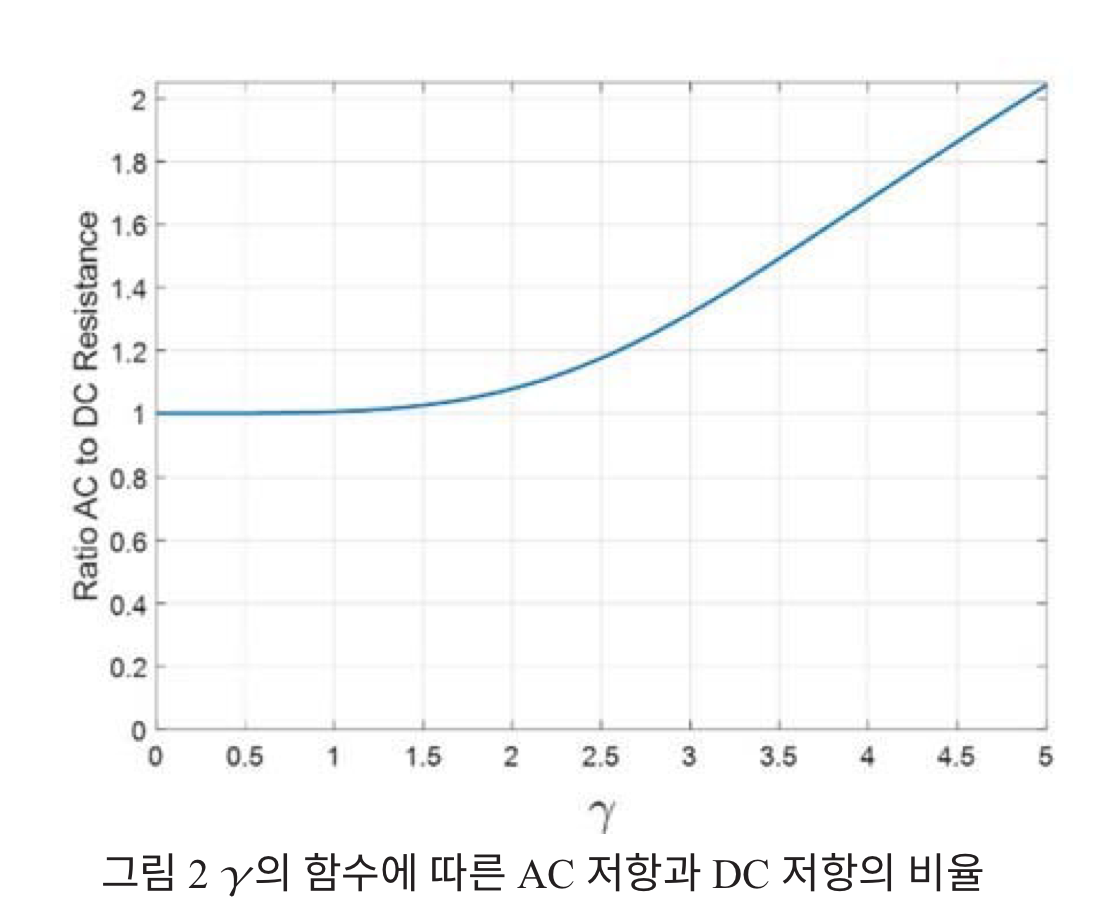

## 2. Proximity Effect

근접 효과는 인접한 도체 및/또는 자석의 회전/움직임에 의해 생성된 외부 자기장 $B_{ext}$  에 의해 유도된 와전류로 인해 발생한다.  그림 2과 같이 와전류가 유도되면 도체에 흐르는 전류가 한쪽으로 집중되고 이때문에 저항이 증가한다.

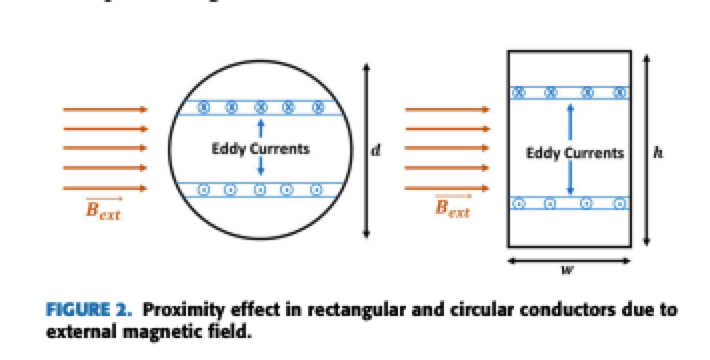

누설자속은 슬롯 옆에서 옴 

### 1D Method 

#### Formular A $g_1$


$$
$$
       
$$g_1({\gamma_w,\gamma_h)=\frac{\gamma_w\gamma_h^3}{6 \cdot \pi^2 \cdot \mu^2 \cdot \sigma}$$


    g1_func = @(gamma_w, gamma_h) (gamma_w .* gamma_h.^3) / (6 * pi^2 * mu_c^2 * sigma);
    coeffg1=calcProxg1(gamma_w, gamma_h);


$$$P_{\text {rect }}=g_1({\gamma_w,\gamma_h)l B_m^2=\\

\frac{\gamma_w\gamma_h^3}{6 \cdot \pi^2 \cdot \mu^2 \cdot \sigma} l B_m^2$$$


  - 정현파 가정                                             

#### Formular B(Improved One) $f_2$, $g_2$ Lenz Law

$$g_2\left(\gamma_w, \gamma_h\right)=\left[\frac{\gamma_w}{\sigma \cdot \mu^2} \cdot \frac{\sinh \left(\gamma_h\right)-\sin \left(\gamma_h\right)}{\cosh \left(\gamma_h\right)+\cos \left(\gamma_h\right)}\right]$$   - calcHybridStrandProxImproved1D  ? > Formula B Lenz Law 

            % g2 함수 정의             % 손실 계산 함수
            g2_func = @(gamma_w, gamma_h) (gamma_w / (sigma * mu_c^2)) * ...
                (sinh(gamma_h) - sin(gamma_h)) / (cosh(gamma_h) + cos(gamma_h));    

-  $$P_{\text {rect }}=\frac{\gamma_w\gamma_h^3}{12 \cdot \pi^2 \cdot \mu^2 \cdot \sigma} l B_m^2$$ 인거같은데?        -calcHybridStrandProx1D

####  MotorCAD , calcHybridProx1DMCAD


$$$P_{a x}=\frac{l_a w_c h_c{ }^3 \sigma(\omega B)^2}{12} \cdot \frac{1}{\left(1+\alpha\left(T-T_0\right)\right)}$$$


## 계산

if isfield(BField,'Br')
                Br = BField.Br;
                Btheta = BField.Bthetam;
                Bm = sqrt(Br.^2 + Btheta.^2);
                % AC 손실 계산
                P_rect              = calcHybridProx1D(gamma_w_prime(1), gamma_h_prime(1), mu_c, sigma, lactive, Bm); %[W
                P_1DrectG1   = lactive * g1_func(gamma_w_prime, gamma_h_prime) .* Bm.^2 ;
                P1DrectG2    = lactive * g2_func(gamma_w_prime, gamma_h_prime) .* Bm.^2 ;
                P_rect_nonGamma     = calcHybridProx1D(w, h, mu0, sigma, lactive, Bm); %[W]
                P_rectMCAD1D        = calcHybridProx1DMCAD(gamma_w, gamma_h, sigma, freqE, lactive, Bm); %[W]


### 2D Method


$$$P_{\text {rect }}=g_{1,2}\left(\gamma_w, \gamma_h\right) l B_r^2+g_{1,2}\left(\gamma_h, \gamma_w\right) l B_{\theta_m}^2$$$


% 사각형 도체의 손실 계산
P_2D = lactive * (g2_func(gamma_w_prime, gamma_h_prime) .* Br.^2 + ...
              g2_func(gamma_h_prime, gamma_w_prime) .* Btheta.^2);

else % 1D 정보만 입력일 경우
                % 1D 정보만 입력된 경우
                Bm = BField.dataTable.GraphValue;
                t= BField.dataTable.Time;
                P_rect      = calcHybridProx1D(gamma_w_prime(1), gamma_h_prime(1), mu_c, sigma, lactive, Bm); %[W
                P_1DInstant = calcACLossWaveform(lactive, w, h, rho, Bm, t);
                P_1DrectG1 = lactive * g1_func(gamma_w_prime, gamma_h_prime) .* Bm.^2 ;
                P1DrectG2 = lactive * g2_func(gamma_w, gamma_h) .* Bm.^2 ;
                
                % P_rect       = calcHybridProx1D(gamma_w_prime(1), gamma_h_prime(1), mu0, sigma, lactive, Bm); %[W]
                P_rectMCAD1D = calcHybridProx1DMCAD(w, h, sigma, freqE, lactive, Bm); %[W]
                % P_rectMCAD1D = calcHybridProx1DMCAD(gamma_w, gamma_h, sigma, freqE, lactive, Bm); %[W]
                P_rect_nonGamma = []; % 값이 없는 경우 빈 배열 할당
                P_2D = []; % 값이 없는 경우 빈 배열 할당
end


[TB]               

        case 'circular'
            % 원형 도체의 계산 (현재 구현되지 않음)
            error('Circular conductor type is not currently implemented.');

        otherwise
            error('Unsupported conductor type. Choose either "rectangular" or "circular".');
    end
end